imgOG = imread("girlpearl.jpg");
fprintf("Original Image:\n")

Original Image:


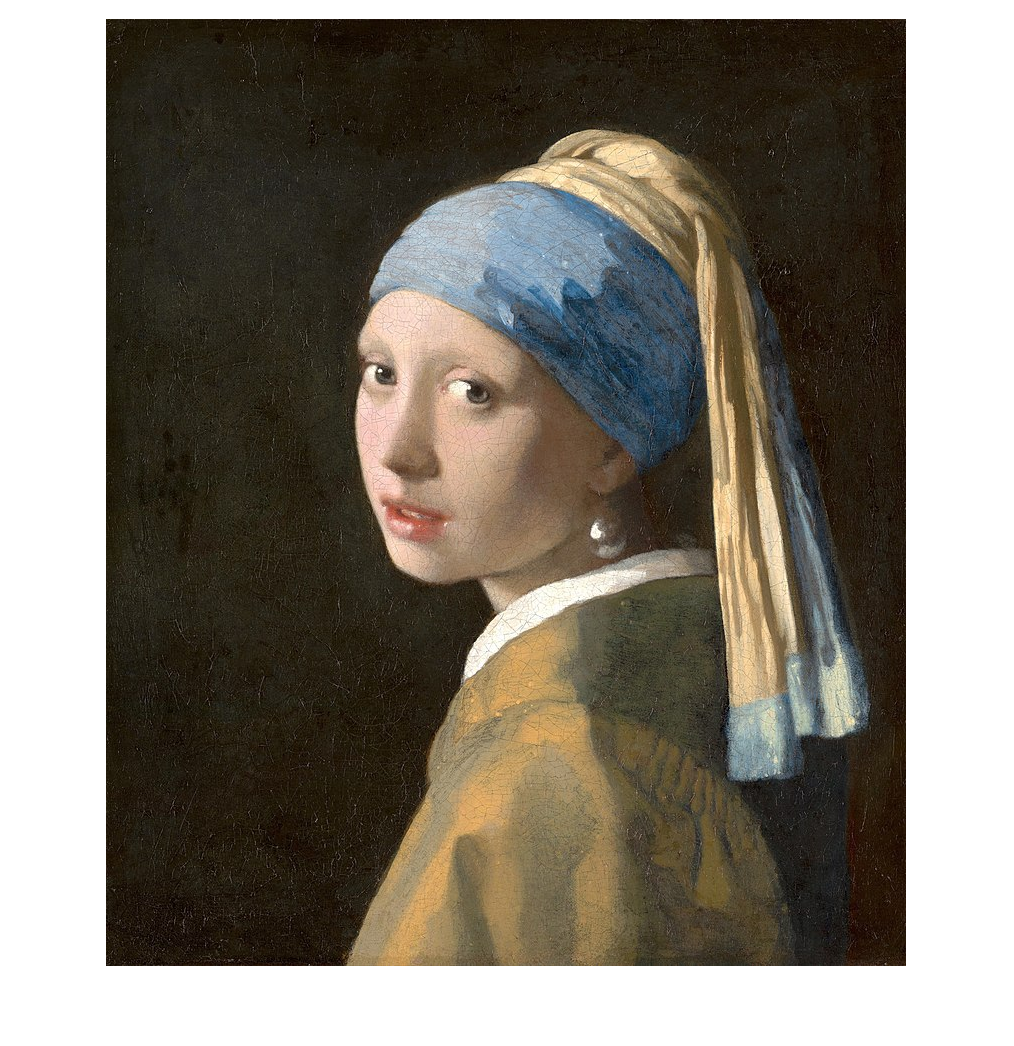

imshow(imgOG)

sizeOG = size(imgOG);
[n,d]=rat(sizeOG(2)/sizeOG(1),.05);
fprintf("Aspect Ratio For Original Image is %d:%d.\n", n,d)

Aspect Ratio For Original Image is 5:6.


%numCol = 100;
%numRow = numCol*(n/d);
imgSmall = imresize(imgOG, [sizeOG(1), sizeOG(2)], "nearest");
%[X, map] = rgb2ind(imgSmall, 0.8,"nodither");
%[imgFinal, mapf] = imresize(X, map,(1/0.02), "nearest");
%fprintf("Pattern:")
%imageViewer(X, map);
%fprintf("Size of pattern is %d columns x %d rows.\n",numCol,numRow)
%imgColorKey  = 1:length(map);
%[ICK, mapck] = imresize(imgColorKey, map,80,"nearest"); 
%imageViewer(ICK, map)
% edges = edge(rgb2gray(imgOG), 'canny', [0.0388, 0.089], 3);
% orgigthresh = [0.0188, 0.0469];
% imageViewer(edges)
% mask = zeros(947,800);
% mask(50:end-50,50:end-50) = 1;
% bw = activecontour(imgOG, mask, 1500, "Chan-vese","SmoothFactor",1,"ContractionBias",0.10);
% imageViewer(bw)
numClusters = 6;
[L, C] = imsegkmeans(imgOG,numClusters,"NumAttempts",6,"MaxIterations",200);
B = labeloverlay(imgOG,L);
pixels = [];
channelr = imgOG(:,:,1);
channelg = imgOG(:,:,2);
channelb = imgOG(:,:,3);
clust_map = zeros(numClusters,3)

clust_map =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


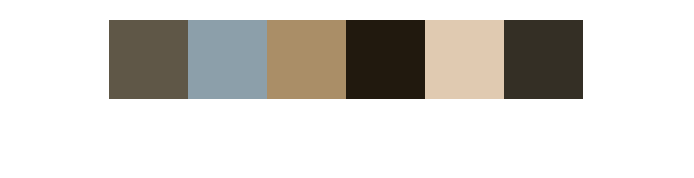

for i = 1:numClusters
    logindex = (L == i);
    pixels = cat(3,pixels,logindex);
    filtered = [channelr(logindex) channelg(logindex) channelb(logindex)];
    avg = [mean(filtered(:,1)) mean(filtered(:,2)) mean(filtered(:,3))];
    clust_map(i,:) = avg/255;
end
imgColorKey  = 1:length(clust_map);
[ICK, mapck] = imresize(imgColorKey, clust_map, 80,"nearest"); 
imshow(ICK,clust_map)

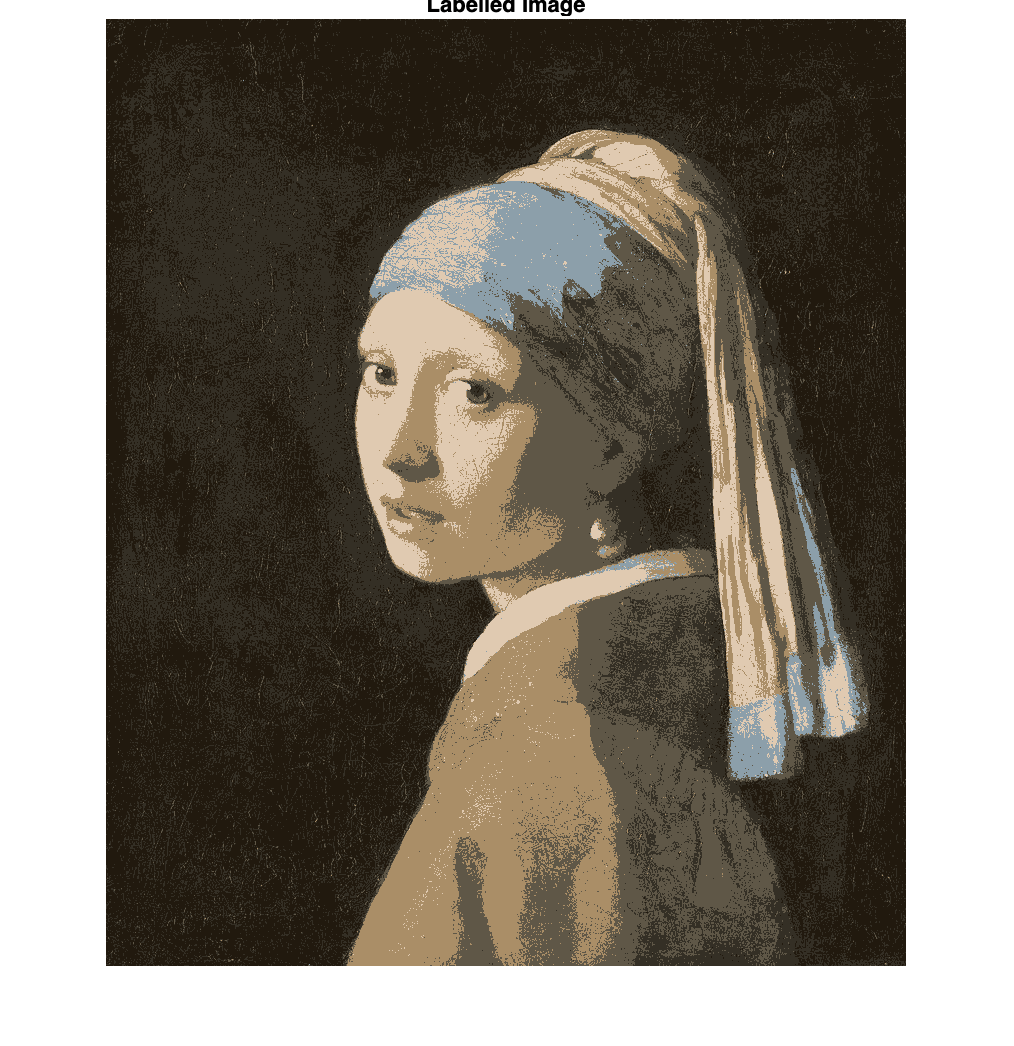

[imind,mapind] = rgb2ind(imgOG,clust_map,"nodither");
imshow(imind, mapind)
title("Labelled Image")